clc;clear;

/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1
     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29



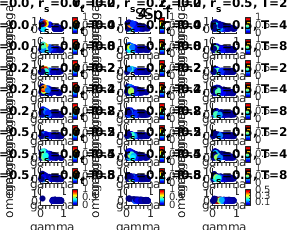

% main_dir = "D:\OneDrive\OneDrive - UW-Madison\Sunduz\processed data\settingSSoS\n100-k2-p_in2btw25-p_out1btw1\";
% main_dir = "C:\OneDrive\OneDrive - UW-Madison\Sunduz\processed data\settingSSoS\n100-k2-p_in2btw25-p_out1btw1\"
main_dir = "/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1/";

rts = ["0", "2", "5"];
rss = ["0", "2", "5"];
ths = ["2", "4", "8"];
data_dir = "r_time0-time_horizon2-r_subject0-num_subjects16\0\";

zS = load(main_dir+data_dir+"z_pred.mat").zS;
G = load(main_dir+data_dir+"G.mat").G;
O = load(main_dir+data_dir+"O.mat").O;
ari = load(main_dir+data_dir+"aris.mat").aris;

% main_dir = 'D:\OneDrive\OneDrive - UW-Madison\Sunduz\SimulationData\settingSSoS\n100-k2-p_in2btw25-p_out1btw1';
main_dir = '/storage08/shuchen/SimulationData/settingSSoT/n500-k10-p_in2btw4-p_out1btw1';

plot_all_ari(main_dir, 1, false);
saveas(gcf,"/storage08/shuchen/Betzel-method/figures/n500/ari_scatter_para_ssot.fig");

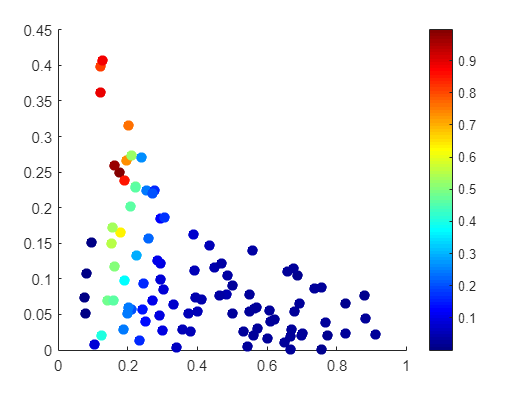

max_color_value = size(ari);
max_color_value = max_color_value(3);
cm = colormap(jet(max_color_value));
mm_ari = squeeze(mean(mean(ari)));

% col = ceil(mm_ari*max_color_value);
sz = 50;

scatter(G,O,sz, mm_ari,"filled");
colorbar;

% for i = 1:1:max_color_value
%     selected_color = cm(col(i),:);
%     plot(G(i),O(i),".","color",selected_color);
%     hold on;
% end